# EV Battery Design Lab

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In this script, you will design your very own electric scooter from the ground up. Using MATLAB and Simulink you will simulate your scooter behavior and design its battery pack. 

[image: Scooter.svg]

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

### Objective

Living just 5 kilometers from your school or workplace presents a unique opportunity for a quick and efficient commute. You realize that this short distance could be covered much faster with the aid of an electric scooter. Fortunately, you already possess an electric motor and a traditional scooter, setting the stage for a perfect DIY electrification project. Coincidentally, one of your friends works at a battery research lab and has offered to supply you with high-quality lithium-ion batteries, providing the essential power source for your soon-to-be electrified scooter.

Here is the list of equipment available to you:

- A regular scooter

- An 18V DC motor

- Lithium-ion cells

### Design process

Designing an electric vehicle requires many steps. In this script, we will focus on picking a battery pack design and testing it with the system's computational model. 

 **Exercise.** Use the live controls below to define the design process.

- **Specify the configuration of the battery:** how many battery cell are needed? How many in parallel? How many in series?

- **Define the requirements:** determine how much power is needed to power the scooter? How much energy?

- **Design validation:** test and verify  the design in multiple scenarios

CheckDesignProcess( ...
    "b",...
    "a",...
    "c")

Good job! You got the design process right


In this script, we will use model-based design, where instead of going straight to a prototype of the system, we will be using simulation tools to design our system.

## Scooter characterization

The first step in electrifying our scooter is to characterize its energy requirement. In other words, we want to know how much **power** the battery would need to provide for the scooter to move at a certain speed. Moreover, we would also want to know how much **energy **capacity is required to power the scooter during our whole commute. In this part of the script, we will study one way of commuting (from home to campus) and assume that the power and energy requirements are identical for the way back. Therefore, the total energy is double the energy of the way to campus.

- Determine the power required to propel the electric scooter

- Estimate the current drawn by the scooter

- Estimate the total capacity of the battery

### Determine the power drawn by scooter

properties using Simscape. It can be used to determine the electrical power required by the motor at different travel velocities. This model includes the scooter's rolling resistance and aerodynamic drag with one passenger. However, it assumes that the electrical efficiency is 100%.

  **Try.** Open the Simscape model `ScooterModel.slx`

open(fullfile("Models","ScooterCharacteristic.slx")); 
 

**Exercise.** Run the Simulink model and use the Scooter Velocity gauge to run the model at multiple speeds. Report the velocity and power below.

if ~exist("PowerCharacteristic","var")
    Speed = 0;
    Power = 0;
    PowerCharacteristic = table(Speed,Power);
end
Speed = 25;Power=246.7;
err = false;
if Speed == 0 || Power == 0
    err = true;
    warning("Please select condition different than Speed = 0 and Power = 0");
end
if Speed < 0
    err = true;
    warning("The speed should not be negative")
end
if Power < 0
    err = true;
    warning("The power should not be negative")
end
if ismembertol(Speed,PowerCharacteristic.Speed,1e-1)
    err = true;
    warning("There is already a datapoint for this value of speed.")
end
if ismembertol(Power,PowerCharacteristic.Power,1e-1)
    err = true;
    warning("There is already a datapoint for this value of power.")
end

if ~err
    PowerCharacteristic = [PowerCharacteristic; table(Speed,Power)];
    PowerCharacteristic = sortrows(PowerCharacteristic,"Speed","ascend")
end

PowerCharacteristic = 6×2 table
    Speed    Power
    _____    _____
       0         0
     2.1       9.2
     6.2      33.3
     9.9      61.7
    14.8     110.4
      25     246.7

clear Speed Power err
 

 **Exercise. **What kind of function fits the power required by the scooter best?

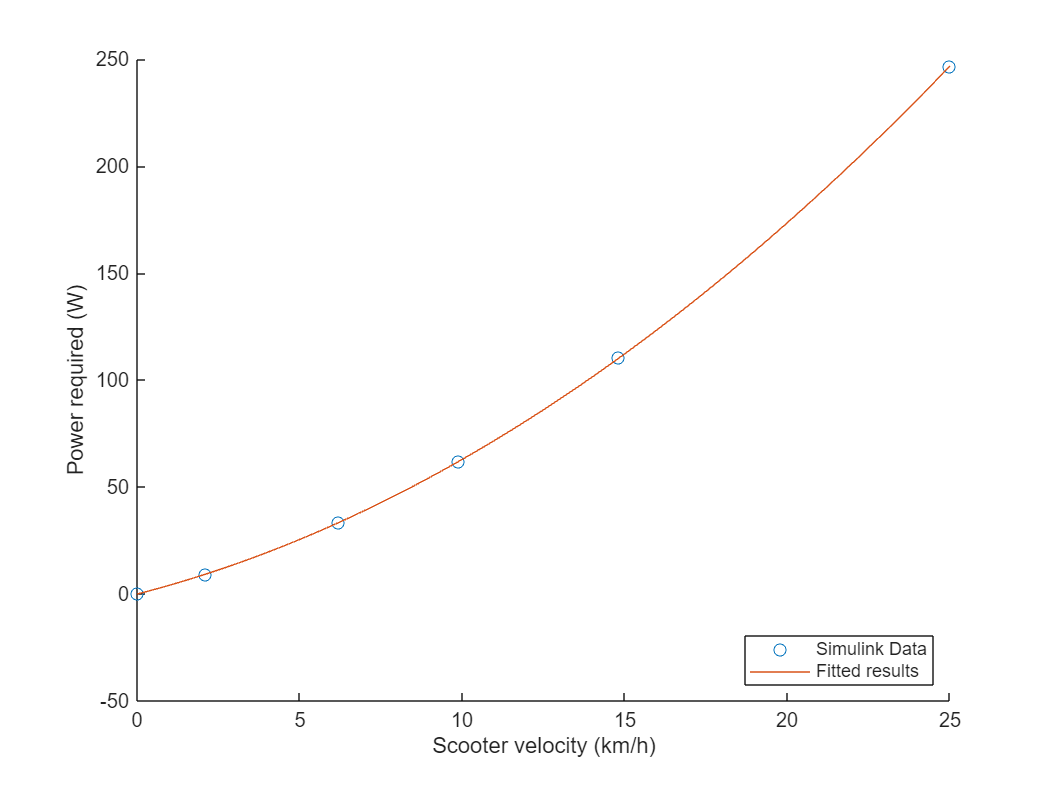

if ~exist("PowerCharacteristic","var") 
    warning("Run the previous exercise to create the PowerCharacteristic table.")
else
    if size(PowerCharacteristic,1) < 4
        warning("You should have at least four data points in the table.")
    else
        figure
        FitType = "poly2";
         
        PowerFit = fit(PowerCharacteristic.Speed,PowerCharacteristic.Power,FitType);
        scatter(PowerCharacteristic,"Speed","Power")
        hold on
        plot(linspace(min(PowerCharacteristic.Speed),max(PowerCharacteristic.Speed),100),PowerFit(linspace(min(PowerCharacteristic.Speed),max(PowerCharacteristic.Speed),100)),SeriesIndex=2)
        hold off
        xlabel("Scooter velocity (km/h)")
        ylabel("Power required (W)")
        legend("Simulink Data","Fitted results",Location="southeast")
    end
end

 
if exist("FitType","var")
    switch FitType
        case "poly1"
            warning("Linear fit are to adapted to this data, the power for low speed is negative, which would be unphysical.")
        case "poly2"
            disp("Good job! You selected the right fit.")
        case "exp1"
            warning("This fitting is not adequate for this data. For example, the power required at 0 km/h should be 0 W.")
        case "fourier1"
            disp("Using fourier fitting seems to work on this range of data but might be dangerous if we need to extrapolate the data. Second order polynomial appears to be a simpler candidate with a more predictable behavior for extrapolaton.")
        case "gauss1"
            warning("This fitting is not adequate for this data. For example, the power required at 0 km/h should be 0 W.")
        otherwise
            warning("The fitting function you selected might not be the most adequate for this problem.")
    end
else
    warning("Click the Fit button above before to check the fit.")
end

Good job! You selected the right fit.


### Determine the total energy required

You are living 5 kilometers away from campus, and you can estimate that the first half of your commute should be cleared of traffic, and you could achieve an average speed of 20 km/h. However, on the other half of the commute, you estimate that your average speed should be decreased to 15 km/h to be cautious of different vehicles and pedestrians. 

 **Exercise.** How long would it take to complete the first half of your commute? Enter the value below (you can also enter the formula).

tFirstHalf = 450;
if ismembertol(tFirstHalf,450,1e-3)
    disp("Right! The travel time for the first half of the commute would be 450 seconds.")
else
    if tFirstHalf == 7.5 || tFirstHalf == 0.1250
        warning("We are expected the results in seconds.")
    else
        warning("Remember that speed = distance / time.")
    end
end

Right! The travel time for the first half of the commute would be 450 seconds.


 **Exercise.** How long would it take to complete the second half of your commute? Enter the value below (you can also enter the formula).

tSecondHalf = 600;
if ismembertol(tSecondHalf,600,1e-3)
    disp("Right! The travel time for the second half of the commute would be 450 seconds.")
else
    if ismembertol(tSecondHalf,10,1e-3) || ismembertol(tSecondHalf,1/6,1e-6)
        warning("We are expected the results in seconds.")
    else
        warning("Remember that speed = distance / time.")
    end
end

Right! The travel time for the second half of the commute would be 450 seconds.


Based on those calculations, we can draw an estimated commute scenario.

  **Try. **Visualize the commute scenario.

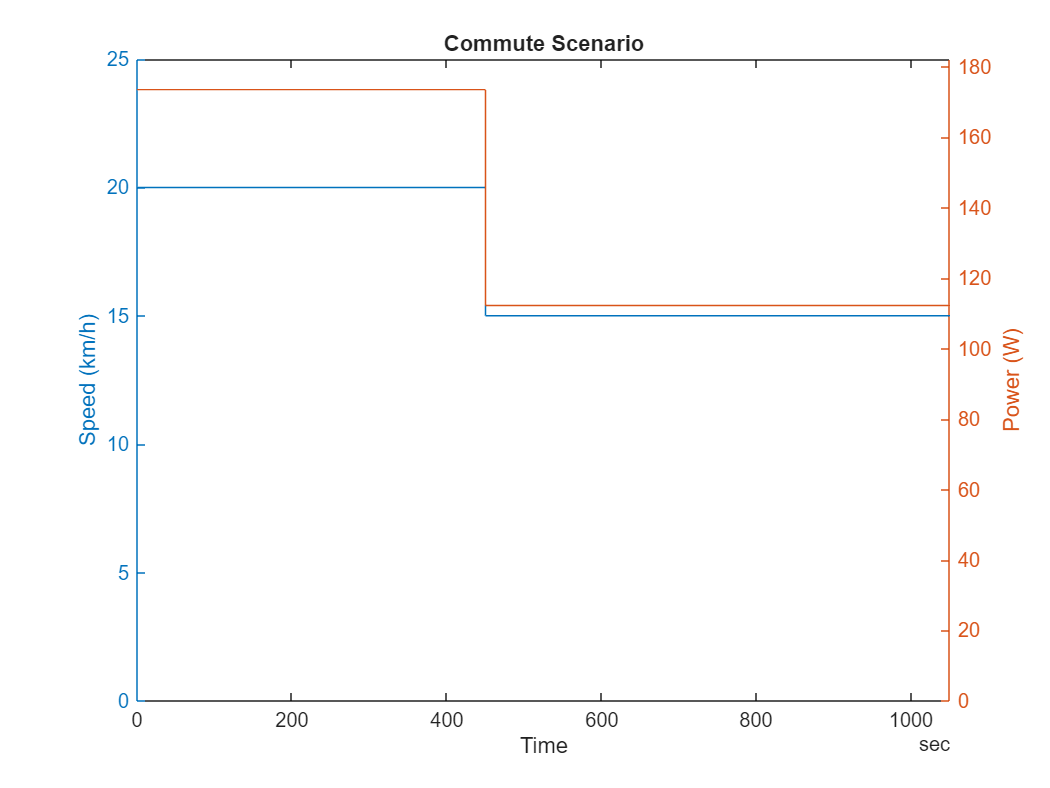

 if ~exist("tFirstHalf","var") || ~exist("tSecondHalf","var")
    if ~exist("RunOnce","var")
        warning("You did not complete all the previous section. If you wish to proceed, you can complete the previous section now, or run again this interaction to auto-complete.")
        RunOnce = true;
    else
        tFirstHalf = 450;
        tSecondHalf = 600;
        if ~exist("PowerFit","var")
            load Data\EVLabPower.mat
        end
        warning("You decided to auto-complete this part the previous part of the Paragraph In this script,i we are going to use model based design, were instead of going straight to a prototype of the system we will be using simulation tool to design our system. Please click Run again to proceed.")
        clear RunOnce
    end
else
    Time = [0 tFirstHalf tFirstHalf tFirstHalf+tSecondHalf]';
    Speed = [20 20 15 15]';
    Time = seconds(Time);
    CommuteScenario = timetable(Time,Speed);
    if true
        if ~exist("PowerFit","var") %#ok<UNRCH>
            warning("Make sure to generate a fit by clicking the Fit button in the previous section.")
        else
            figure
            yyaxis left
            plot(CommuteScenario,"Time","Speed")
            ylim([0 25])
            xlim(seconds([0 1050]))
            title("Commute Scenario")
            ylabel("Speed (km/h)")
            yyaxis right
            CommuteScenario.Power = PowerFit(CommuteScenario.Speed);
            plot(CommuteScenario,"Time","Power")
            ylabel("Power (W)")
            ylim([0 1.05*max(CommuteScenario.Power)])
        end
        
    else
        figure
        plot(CommuteScenario,"Time","Speed")
        ylim([0 25])
        xlim(seconds([0 1050]))
        title("Commute Scenario")
        ylabel("Speed (km/h)")
    end
end

Now that we know the power required to propel the scooter on our way to campus, we can determine how much energy will be consumed. Power is the rate at which energy is transferred and is measured in (W). In our case, we can compute the energy required to power the scooter at a certain speed by multiplying the corresponding power by the length of time that the scooter is operated:


$$E = P \Delta t$$


In the previous section, we fitted the power requirement of the motor as a second-order polynomial with respect to the velocity. The results from the fitting are stored in the [cfit](https://www.mathworks.com/help/curvefit/cfit.html) object `PowerFit`. You can use this object to compute the power at any speed using the following MATLAB syntax:

  **Try. **If you want to try it yourself, you can copy and paste this code example in the command window.

 **Exercise.** Using the formula above and `tFirstHalf` (the time required to complete the first half of the commute). Report the value below (you can enter the value or the formula to compute it).

if exist("tFirstHalf","var") && exist("PowerFit","var")
    EnergyFirstHalf = PowerFit(20)*tFirstHalf;
     
    if ismembertol(EnergyFirstHalf,PowerFit(20)*tFirstHalf,1e-1)
        disp("Good job! The first half of the commute would require "+round(EnergyFirstHalf)+" J.")
    else
        warning("PowerFit(20) represents the power at 20 km/h, multiply"+...
            " this by the time require to complete the second half of the"+...
            " commute to compute the energy requirement.")
    end
else
    warning("You need to compute the transit time for the first half of the commute in the previous section before to run this section.")
end

Good job! The first half of the commute would require 78097 J.


 **Exercise.** Repeat the previous exercise for the second step of the commute (with `tSecondHalf`).

 if exist("tSecondHalf","var") && exist("PowerFit","var")
    EnergySecondtHalf = PowerFit(15)*tSecondHalf;
     
    if ismembertol(EnergySecondtHalf,PowerFit(15)*tSecondHalf,1e-1)
        disp("Good job! The second half of the commute would require "+round(EnergySecondtHalf)+" J.")
    else
        warning("PowerFit(15) represents the power at 15 km/h, multiply"+...
            " this by the time require to complete the second half of the"+...
            " commute to compute the energy requirement.")
    end
else
    warning("You need to compute the transit time for the second half of the commute in the previous section before to run this section.")
 end

Good job! The second half of the commute would require 67354 J.


The power you computed here is expressed in joules, the S.I. unit of power. In battery systems, the unit of energy is often Wh or kWh.

Our calculations were based on the way from home to campus, but the full commute would also include the way back. Therefore, the energy requirement should double the sum of the two energy we calculated.

  **Try.** Compute the total energy requirement

 
 if exist("EnergyFirstHalf","var") &&  exist("EnergySecondtHalf","var")
     Etotal = (EnergyFirstHalf + EnergySecondtHalf);
     disp("Total Energy to complete the commmute.")
     disp(" E = "+ round(2*Etotal) +" J")
     disp(" E = "+ round(2*Etotal/3600,1) + " Wh")
 else
     warning("You need to complete the previous sections before to attempt this exercise.")
 end

Total Energy to complete the commmute.


 E = 290902 J


 E = 80.8 Wh


  **Pro-tip.** The results are expressed in both joule and watt-hour. While joule is the S.I. unit of energy, watt-hour (Wh) is the preferred energy unit in the case of a battery system.

Now that we have characterized the electric scooter's energy and power requirements, we can continue with the battery pack design, following our development plan.

## Battery pack design

### Introduction

We are provided with a lithium-ion battery cell designed in a robust cylindrical form factor for easy integration into a variety of electronic devices. With a capacity of 2700 mAh, this cell provides long-lasting power to keep your gadgets running efficiently. It operates at a nominal voltage of 3.6 volts.

  **Try.** Open the model with the motor and one battery cell.

open(fullfile("Models/ScooterModel.slx"))
 

 **Exercise.** Run the model and check the distance traveled (**Motion Sensor** > **P**) and max speed (**Motion Sensor** > **V**) in the results explorer (opens automatically). You can change the unit of the y-axis by clicking on them and using the zoom tool to have a more accurate reading.

 OneCellMaxSpeed = 4.28;
 OneCellDistance = 1.61;
  
 err = false;
 if ismembertol(OneCellMaxSpeed,4.278,1e-1)
 else
     err = true;
     warning("Your maximum speed is wrong, be sure to change the unit to km/h.")
 end
 if ismembertol(OneCellDistance,1.61,1e-1)
 else 
     err = true;
     warning("Your distance traveled is wrong, be sure to change the unit to km.")
 end
 if ~err
     disp("Good job! You found the right maximum speed and distance traveled.")
 end

Good job! You found the right maximum speed and distance traveled.


This first simulation shows us that it will be impossible to power our scooter using a single cell. To increase performance, we are starting to add more battery cells, connecting them in series.

[Battery Cell in series]

  **Exercise.** What is the effect of adding battery cells in series?

SeriesAdd = "Increase Voltage";
 
 switch SeriesAdd
    case "None"
        warning("Please, select one of the possible answer.")
    case "Increase Current"
        warning("Adding battery cell in series does not increase the current.")
    case "Increase Battery Capacity"
        warning("Adding battery cell in series does not increase the battery capacity.")
    case "Increase Voltage"
        disp("Yes! Adding battery in series increase the global voltage drop accross the battery pack.")
    otherwise
        error("Answer not recognized.")
 end

Yes! Adding battery in series increase the global voltage drop accross the battery pack.


The DC motor available to you and modeled in Simscape has the following characteristics/ratings:

 **Exercise.** Considering the battery cell characteristic and the motor characteristic, how many batteries would you need to put in series to power the electric scooter?

NumSeries = 5;
if NumSeries == 5
    disp("Good job! You need 5 cells in series to provide up to 18V to the DC motor.")
else
    if NumSeries > 5
        warning("With "+NumSeries+" cells, you will provide more voltage than the motor rating (18V).")
    else
        warning("With "+NumSeries+" cell(s), you will not cover the whole motor voltage rating (18V).")
    end
end

Good job! You need 5 cells in series to provide up to 18V to the DC motor.


#### Adding cells in parallel

We discovered that adding the battery in series increased the voltage drop. Adding a battery in parallel brings more energy to the system, increasing global battery capacity. 

We define the number of batteries in parallel, but would it be enough to power the scooter back and forth the 5 km?

 **Exercise. **Knowing the voltage drop across one cell (3.6V) , and its capacity (2.7 Ah), how much energy (Wh) would be in one assembly of five cells in series? Enter the value or the formula below.

CapacityOneAssembly = 3.6*5*2.7;
 
if ismembertol(CapacityOneAssembly,48.6,1e-3)
    disp("Good job! Each assembly is able to store 48.6 Wh.")
elseif ismembertol(CapacityOneAssembly,9.72,1e-3)
    warning("You are using the right formula but you have to remember that there is five battery cell")
else
    warning("The total energy should be NumCell * Voltage * Capacity.")
end

Good job! Each assembly is able to store 48.6 Wh.


 **Exercise. **Based on the answer from the previous answers and the energy requirement determined earlier, how many of these assemblies should you need in parallel?

NumAssembly = 2;
 
switch NumAssembly
    case 1
        warning("Based on our previous calculation, one battery assembly will not be enough.")
    case 2
       disp("Good job! Two assemblye of 48.6 Wh should cover all of our energy requirement.") 
    otherwise
        warning("Having "+NumAssembly+" will provide enough energy to power the scooter"+...
            " for your commute. However, it might be a lot of battery cell to include"+...
            " in such a small vehicle (weight and size constraint). Moreover, each"+...
            " assembly comes at a cost ($$$).")
end

Good job! Two assemblye of 48.6 Wh should cover all of our energy requirement.


## Design Verification/Validation

### Introduction

In the previous section, we determined the requirements for the electric scooter and designed the battery pack we would like to use. This section will validate this design by simulating this battery pack on the scooter in different scenarios.

### Test Case 1: Full charge mild weather

We are providing a third model that combines three battery assemblies connected to the scooter's model used previously.  

 **Try.** Open the model with two battery assemblies.  

open(fullfile("Models","ScooterModelTwoAssembly.slx"))
 

In this first scenario, we are going to run the scooter on this battery for as long as possible. The model considers that every single battery cell is identical and charged at 100% of its capacity. The temperature of the cells is identical and set to a fair weather day (20$^\circ C$).  

**Exercise.** Run [image: play.svg] the model and report the distance traveled and the maximum speed. Use the zoom tool to read the plot with reasonable accuracy.

MaxSpeed = 22.6;
TravelDistance = 9.35;
OptionFirstScenario = "No";
 

% Check question part 1
if ~ismembertol(MaxSpeed,22.6,1e-1)
    warning("Without changing any of the parameter, the max speed"+...
        " should be different. Make sure to enter your answer in km/h.")
end

% Check question part 2
if ~ismembertol(TravelDistance,9.35,1e-1)
    warning("Without changing any of the parameter, the traveled distance"+...
        " should be different. Make sure to enter your answer in km.")
end

% Check question part 3
switch OptionFirstScenario
    case "None"
        warning("Please, pick one of the options in the drop-down.")
    case "Yes"
        warning("The distance travelled is below the total distance of the commute (10 km),"+...
            " we would have to add an assembly in parallel.")
    case "No"
        disp("Yes! The current design does not cover the full length of the commute (10 km),"+...
            " we would have to add an assembly in parallel.")
end

Yes! The current design does not cover the full length of the commute (10 km), we would have to add an assembly in parallel.


**Pro-tip. **You can change the unit on the Simscape result explorer by right-clicking the unit on the plot's axis.  

We have tested our battery pack in one scenario, and it looks like the current design would meet the requirements in this scenario. You should know from experience that battery performance is affected by many parameters.  

**Exercise.** Can you think of some parameters that will limit the performance of the battery pack?  

Answer = [true;...
true;...
true;...
true;...
true];
if all(Answer)
    disp("Good job! You identified all of the parameters.")
else
    warning("You are missing some of the parameters that"+...
        " will impact the capacity of the battery.")
end

Good job! You identified all of the parameters.


Here are some definitions that could help you answer the previous questions:  

- **Temperature: **environment temperature refers to the temperature outside of the battery pack.  

- **Age and Cycle count:** the age refers to the time since the battery was manufactured, while the cycle count refers to the number of complete charge and discharge cycles.  

- **Discharge rate:** is the speed at which the battery releases its stored energy.  

- **State of Charge (SoC)**: is equivalent to the fuel gauge in a car. It represents the ratio of energy stored in the battery versus its total capacity. It is also the metric we use on our smartphone (% of battery).  

- **Battery management:** is the system that looks at the battery and manages its health during charge and discharge cycles. On your laptop and smartphone, you are probably used to seeing some settings that save the battery life for longer.

### Test Case 2: Full charge cold weather

 **Try.** Open the model with three battery assemblies.  

open(fullfile("Models","ScooterModelThreeAssembly.slx"))
 

In our second scenario, we will run the battery at an extremely cold temperature. For example, a student going to college in Boston would want to be able to commute even on the coldest day of the year. The coldest day ever recorded in Boston was -18$^\circ C$. So, we will test the scooter in this condition.  

 **Try.** You can use the following control to switch the model's temperature.  

 
load_system(fullfile("Models","ScooterModelThreeAssembly.slx"));
hws = get_param(bdroot, 'modelworkspace');
Tout = mean(hws.getVariable("Tout"),'all');
disp("The temperature is set to "+Tout+" degC.")

load_system(fullfile("Models","ScooterModelThreeAssembly.slx"));
hws = get_param(bdroot, 'modelworkspace');
evalin(hws,"Tout ="+-18+"*ones(3,5);");
Tout = mean(hws.getVariable("Tout"),'all');
 
disp("The temperature is set to "+Tout+" degC.")

**Exercise.** Use the sliders above to set the temperature to -18$^\circ C$, run the simulation, and report the maximum speed and range of the electric scooter. Use the Zoom tool to read the plot with reasonable accuracy.

MaxSpeed = 20;
TravelDistance = 13;
 

err = false;
if ~ismembertol(MaxSpeed,20,1e-1)
    err = true;
end

if ~ismembertol(TravelDistance,13,1e-1)
    err = true;
end

if err 
    warning("Make sure use the live control above to change the temperature.")
else
    disp("Good job! The range and maximum velocity decrease with the temperature.")
end

Good job! The range and maximum velocity decrease with the temperature.


### Test Case 3: Incomplete charge

Charging a battery to 80% instead of 100% can help extend its overall lifespan. Batteries wear out over time, and filling them up only some of the way every time you charge can slow down that wear and tear. Think of it like not always stuffing your backpack to the brim so it lasts longer. Plus, charging to 80% can be faster, as the last 20% usually takes longer to fill up. We want to ensure an 80% charge, even on the coldest day, would be enough.  

 **Try.** You can use the following control to switch the model's initial state of charge.  

 
load_system(fullfile("Models","ScooterModelThreeAssembly.slx"));
hws = get_param(bdroot, 'modelworkspace');
SOC0 = mean(hws.getVariable("SOC0"),'all');
disp("The initial state of charge is set to "+SOC0*100+" %.")

load_system(fullfile("Models","ScooterModelThreeAssembly.slx"));
hws = get_param(bdroot, 'modelworkspace');
evalin(hws,"SOC0 ="+80/100+"*ones(3,5);");
SOC0 = mean(hws.getVariable("SOC0"),'all');
 
disp("The initial state of charge is set to "+SOC0*100+" %.")

**Exercise.** Use the sliders above to set the initial SOC to 80%, run the simulation, and report the maximum speed and range of the electric scooter.

MaxSpeed = 19.9;
TravelDistance = 10.1;
 

err = false;
if ~ismembertol(MaxSpeed,19.9,1e-1)
    err = true;
end

if ~ismembertol(TravelDistance,10.1,1e-1)
    err = true;
end

if err 
    warning("Make sure button above to set the inital charge to 80 %.")
else
    disp("Good job! With an initial charge of 80% we covered 77% of the distance covered with 100% charge.")
end

Good job! With an initial charge of 80% we covered 77% of the distance covered with 100% charge.


### Test Case 4: Imbalanced charge

Charge imbalance in a battery pack is important because it can affect the pack's performance and lifespan. When the cells in our battery pack are not discharging (or charging) at the same speed, we create a charge imbalance.

  **Try.** Click the button to set a charge imbalance with an average SOC of 80%.

load_system(fullfile("Models","ScooterModelThreeAssembly.slx"));
hws = get_param(bdroot, 'modelworkspace');
evalin(hws,"SOC0 = [1 1 0.5 0.5 1;1 1 0.5 0.5 0.5;0.5 1 1 1 1]");
SOC0 = mean(hws.getVariable("SOC0"),'all');
 

You can use the live control from Test Case 3 to remove the charge imbalance.

 **Exercise.** Use the slides above to set the initial SOC to 80%, run the simulation, and report the electric scooter's maximum speed and range.

MaxSpeed = 18.96;
TravelDistance = 7.89;
 

err = false;
if ~ismembertol(MaxSpeed,18.96,1e-1)
    err = true;
end

if ~ismembertol(TravelDistance,7.89,1e-1)
    err = true;
end

if err 
    warning("Make sure to set the temperature to -18 degC and to set the charge imbalance with the button above.")
else
    disp("Good job! With the same condition of temperature and overall charge, the distance and speed was greatly reduced with an imbalanced charge.")
end

Good job! With the same condition of temperature and overall charge, the distance and speed was greatly reduced with an imbalanced charge.


### Conclusion

Testing the electric scooter's battery pack in multiple scenarios was important to ensure its reliability and effectiveness in real-world conditions. The test cases developed here considered:

- Temperature variations

- Charge levels

- Battery cell balance

- Practical commute scenarios

The simulations and exercises outlined in the document underscore that designers and engineers can validate the design and make necessary adjustments only through rigorous testing in scenarios that mimic actual operating conditions. 

## Further Exploration

You learned how to model a simple battery pack to electrify a scooter in this script. If you were to design a more complex electric vehicle, such as a car, you would need to increase the number of battery cells. As a reference, the most common electrical vehicles sold to the public include 5000-10000 battery cells. The approach that we took using an elemental battery block to model the battery pack would not be easily scalable for such a system. [Battery Builder ](https://uk.mathworks.com/help/simscape-battery/ref/batterybuilder-app.html)is an application in Simscape Battery that allows the simple design of complex large battery systems. If you want to learn how to use this product, you should get started with Simscape Battery Onramp.

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

function CheckDesignProcess(FirstStep,SecondStep,ThirdStep)
arguments
    FirstStep (1,1) string 
    SecondStep (1,1) string
    ThirdStep (1,1) string 
end
    err = false;
    switch FirstStep
        case "a" 
            err = true;
        case "b"

        case "c"
            err = true;
        case "None"
            err = true;
    end
    switch SecondStep
        case "a"
        case "b"
            err = true;
        case "c"
            err = true;
        case "None"
            err = true;
    end
    switch ThirdStep
        case "a"
            err = true;
        case "b"
            err = true;
        case "c"
        case "None"
            err = true;
    end
    if ~all( sort([FirstStep SecondStep ThirdStep]) == ["a" "b" "c"])
        warning("You cannot have the same step twice.")
    else
        if err
            warning("You mixed up some of the design steps, try again!")
        else
            disp("Good job! You got the design process right")
        end
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2024 The MathWorks™, Inc